# **第三章**

3.47 利用matlab函数工具箱函数zplane(b,a)，画出下列Z变换的零极点分布图，并给出所有可能的收敛域及对应序列的特性（左边序列，右边序列，双边序列）。

（1）${\mathrm{X}}_1 {\left(z\right)}=\frac{2z^4 +16z^3 +44z^2 +56z+32}{3z^4 +3z^3 -15z^2 +18z-12}$

  (2)  ${\mathrm{X}}_2 {\left(z\right)}=\frac{4z^4 -8.68z^3 -17.98z^2 +26.74z-8.04}{z^4 -2z^3 +10z^2 +6z+65}$

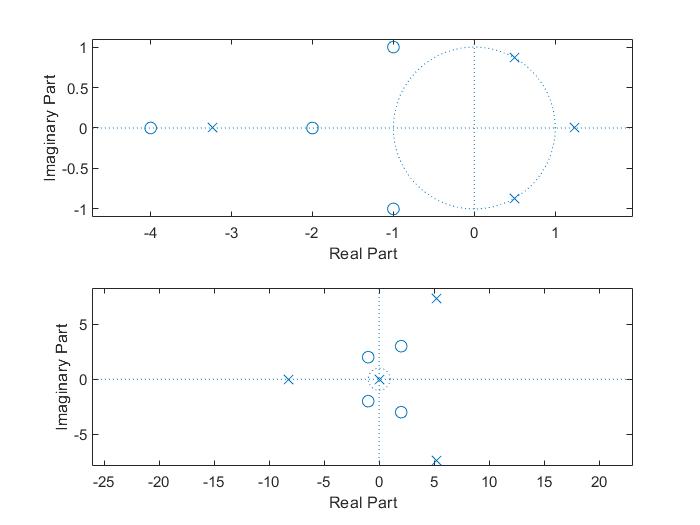

A=[3 3 -15 18 -12];
B=[2 16 44 56 32];
figure(1)
subplot(2,1,1)
zplane(B,A)
A=[4 -8.68 -17.98 2674 -8.04];
B=[1 -2 10 6 65];
subplot(2,1,2)
zplane(B,A)

3.49  设线性时不变因果系统的差分方程为$\begin{array}{l}
\mathrm{y}{\left(\mathrm{n}\right)}=-0.6\mathrm{y}{\left(\mathrm{n}-1\right)}-0.68\mathrm{y}{\left(\mathrm{n}-2\right)}-0.55\mathrm{y}{\left(\mathrm{n}-3\right)}+0.477\mathrm{y}{\left(\mathrm{n}-4\right)}+3\mathrm{x}{\left(\mathrm{n}\right)}\\
=1.2\mathrm{x}{\left(\mathrm{n}-1\right)}-5.22\mathrm{x}{\left(\mathrm{n}-2\right)}-1.548\mathrm{x}{\left(\mathrm{n}-3\right)}+0.359\mathrm{x}\left(\mathrm{n}-4\right)
\end{array}$ 利用matlab函数zplane(b,a)，画出系统的零极点分布，并判断系统是否稳定。

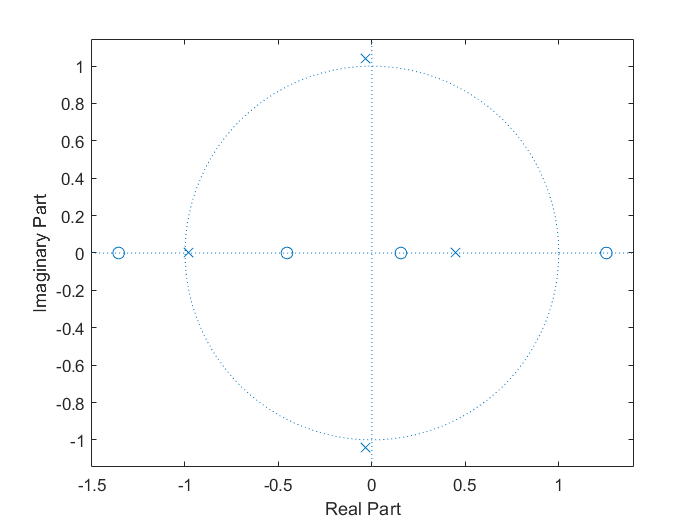

A=[1 0.6 0.68 0.55 -0.477];
B=[3 1.2 -5.22 -1.548 0.359];
figure(2)
zplane(B,A)

3.51 设线性时不变系统的系统函数为


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathrm{H}{\left(\mathrm{z}\right)}=\frac{z^2 +5z-50}{2z^4 -2.98z^3 +0.17z^2 +2.3418z-1.5147}$$


- 利用matlab语言所得系统的极点分布判断系统是否稳定。

- 用输入单位阶跃序列u(n)检验系统是否稳定。

- 如果系统稳定，求系统对于单位阶跃序列的相应。

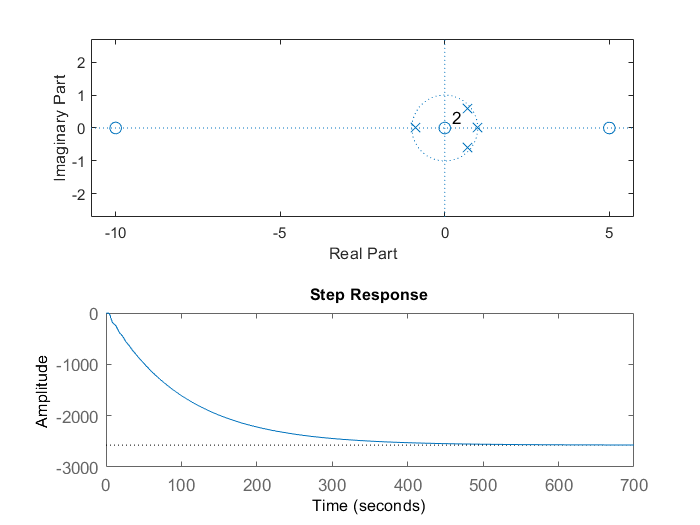

A=[2 -2.98 0.17 2.3418 -1.5147];
B=[1 5 -50];
figure(3)
subplot(2,1,1)
zplane(B,A);

subplot(2,1,2)
dstep(B,A);

3.52 M点滑动平均系统的单位脉冲响应


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;h{\left(n\right)}={\left\{\begin{array}{c}
\frac{1}{M},0\le n\le M-1\\
0,其它
\end{array}\right)}$$


利用matlab工具箱函数freqz，abs和angle，画出M=7，该系统的幅频响应曲线和相频响应曲线，并解释相频响应曲线不连续的原因。

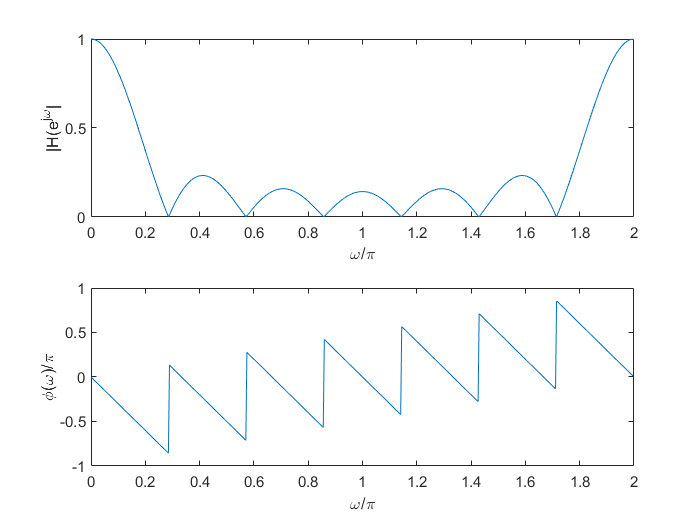

h1=1./7*ones(1,7);
[H,w]=freqz(h1,1,'whole');
figure(4)
subplot(2,1,1)
plot(w/pi,abs(H))
xlabel('\omega/\pi');ylabel('|H(e^j^\omega|');
subplot(2,1,2)
plot(w/pi,angle(H)/pi);
xlabel('\omega/\pi');ylabel('\phi(\omega)/\pi');